# Generate Text Using Deep Learning

## Load Training Data

Extract the text data from the text file `sonnets.txt`.

folderPath = 'data/'; % Path to the folder containing text files
files = dir(fullfile(folderPath, '*.txt')); % List all .txt files

speeches = {}; % Cell array to store the content of each speech
metadata = {}; % Cell array to store metadata of each speech

for k = 1:length(files)
    filePath = fullfile(folderPath, files(k).name); % Full path to a file
    fileID = fopen(filePath, 'r');
    fileContents = fread(fileID, '*char')'; % Read the content as characters
    fclose(fileID);

    % Extract metadata and speech using text parsing, assuming a fixed structure
    metaEndIndex = strfind(fileContents, '---'); % Find end of metadata section
    if length(metaEndIndex) >= 2
        metaSection = fileContents(1:metaEndIndex(2));
        speechSection = fileContents(metaEndIndex(2)+3:end); % Adjust based on exact structure

        % Store metadata and speech in separate cell arrays
        metadata{k} = metaSection;
        speeches{k} = speechSection;
    end
end

speeches = speeches'

speeches = 59×1 cell array
    {'←↵←↵Fellow-countrymen: At this second appearing to take the oath of the presidential office, there is less occasion for an extended address than there was at the first. Then a statement, somewhat in detail, of a course to be pursued, seemed fitting and proper. Now, at the expiration of four years, during which public declarations have been constantly called forth on every point and phase of the great contest which still absorbs the attention and engrosses the energies of the nation, little that is new could be presented. The progress of our arms, upon which all else chiefly depends, is as well known to the public as to myself; and it is, I trust, reasonably satisfactory and encouraging to all. With high hope for the future, no prediction in regard to it is ventured.←↵←↵On the occasion corresponding to this four years ago, all thoughts were anxiously directed to an impending civil war. All dreaded it—all sought to avert it. While the inaugural address wa

## Convert Text Data to Sequences

Convert the text data to sequences of vectors for the predictors and categorical sequences for the responses.

Create special characters to denote "start of text", "whitespace", "end of text" and "newline". Use the special characters `"\x0002"` (start of text), `"\x00B7"` ("·", middle dot), `"\x2403"` ("␃", end of text), and `"\x00B6"` ("`¶`", pilcrow) respectively. To prevent ambiguity, you must choose special characters that do not appear in the text. Because these characters do not appear in the training data, they can be used for this purpose.

startOfTextCharacter = compose("\x0002");
whitespaceCharacter = compose("\x00B7");
endOfTextCharacter = compose("\x2403");
newlineCharacter = compose("\x00B6");

For each observation, insert the start of text character at the beginning and replace the whitespace and newlines with the corresponding characters.

for i = 1:numel(speeches)
    % Remove leading and trailing spaces
    speeches{i} = strtrim(speeches{i});
    % Replace multiple spaces with a single space
    speeches{i} = regexprep(speeches{i}, '\s+', ' ');  
end

speeches = startOfTextCharacter + speeches;
speeches = replace(speeches,[" " newline],[whitespaceCharacter newlineCharacter]);

Create a vocabulary of the unique characters in the text.

uniqueCharacters = unique([speeches{:}]);
numUniqueCharacters = numel(uniqueCharacters);


Loop over the text data and create a sequence of vectors representing the characters of each observation and a categorical sequence of characters for the responses. To denote the end of each observation, include the end of text character.

numDocuments = numel(speeches);
XTrain = cell(1,numDocuments);
YTrain = cell(1,numDocuments);
for i = 1:numel(speeches)
    characters = speeches{i};
    sequenceLength = numel(characters);
    
    % Get indices of characters.
    [~,idx] = ismember(characters,uniqueCharacters);
    
    % Convert characters to vectors.
    X = zeros(numUniqueCharacters,sequenceLength);
    for j = 1:sequenceLength
        X(idx(j),j) = 1;
    end
    
    % Create vector of categorical responses with end of text character.
    charactersShifted = [cellstr(characters(2:end)')' endOfTextCharacter];
    Y = categorical(charactersShifted, [string(uniqueCharacters(2:end)'); endOfTextCharacter]);
    XTrain{i} = X;
    YTrain{i} = Y;
end

View the first observation and the size of the corresponding sequence. The sequence is a *D*-by-*S* matrix, where *D* is the number of features (the number of unique characters) and *S* is the sequence length (the number of characters in the text).

disp(speeches{1});

□Fellow-countrymen:·At·this·second·appearing·to·take·the·oath·of·the·presidential·office,·there·is·less·occasion·for·an·extended·address·than·there·was·at·the·first.·Then·a·statement,·somewhat·in·detail,·of·a·course·to·be·pursued,·seemed·fitting·and·proper.·Now,·at·the·expiration·of·four·years,·during·which·public·declarations·have·been·constantly·called·forth·on·every·point·and·phase·of·the·great·contest·which·still·absorbs·the·attention·and·engrosses·the·energies·of·the·nation,·little·that·is·new·could·be·presented.·The·progress·of·our·arms,·upon·which·all·else·chiefly·depends,·is·as·well·known·to·the·public·as·to·myself;·and·it·is,·I·trust,·reasonably·satisfactory·and·encouraging·to·all.·With·high·hope·for·the·future,·no·prediction·in·regard·to·it·is·ventured.·On·the·occasion·corresponding·to·this·four·years·ago,·all·thoughts·were·anxiously·directed·to·an·impending·civil·war.·All·dreaded·it—all·sought·to·avert·it.·While·the·inaugural·address·was·being·delivered·from·this·place,·devo

size(XTrain{1})

ans =           87        3938


View the corresponding response sequence. The sequence is a 1-by-*S* categorical vector of responses.

YTrain{1}

ans = 1×3938 categorical array
     F      e      l      l      o      w      -      c      o      u      n      t      r      y      m      e      n      :      ·      A      t      ·      t      h      i      s      ·      s      e      c      o      n      d      ·      a      p      p      e      a      r      i      n      g      ·      t      o      ·      t      a      k      e      ·      t      h      e      ·      o      a      t      h      ·      o      f      ·      t      h      e      ·      p      r      e      s      i      d      e      n      t      i      a      l      ·      o      f      f      i      c      e      ,      ·      t      h      e      r      e      ·      i      s      ·      l      e      s      s      ·      o      c      c      a      s      i      o      n      ·      f      o      r      ·      a      n      ·      e      x      t      e      n      d      e      d      ·      a      d      d      r      e      s      s      ·      t      h    

## Create and Train LSTM Network

Define the LSTM architecture. Specify a sequence-to-sequence LSTM classification network with 200 hidden units. Set the feature dimension of the training data (the number of unique characters) as the input size, and the number of categories in the responses as the output size of the fully connected layer.

inputSize = size(XTrain{1},1);
numHiddenUnits = 100;
numClasses = numel(categories([YTrain{:}]));

layers = [
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits,'OutputMode','sequence')
    fullyConnectedLayer(numClasses)
    softmaxLayer];

pool = gcp('nocreate'); % Get the current parallel pool
if isempty(pool)
    parpool; % Create a new parallel pool if none exists
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Preserving jobs with IDs: 2 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile Processes. To create 'myCluster' use 'myCluster = parcluster('Processes')'.
Connected to parallel pool with 8 workers.


Specify the training options. Choosing among the options requires empirical analysis. To explore different training option configurations by running experiments, you can use the Experiment Manager app. 

- Train using the Adam optimizer.

- Specify the number of training epochs as 1000 and the initial learn rate as 0.01. 

- Set the learn rate drop factor to 0.05 and the learn rate drop period to 50.

- Set the gradient threshold to 10. 

- The mini-batch size option specifies the number of observations to process in a single iteration. Specify a mini-batch size that evenly divides the data to ensure that the function uses all observations for training. Otherwise, the function ignores observations that do not complete a mini-batch. Set the mini-batch size to 77.

- Specify to shuffle the data every epoch by setting the `'Shuffle'` option to `'every-epoch'`. 

- To monitor the training progress, set the `'Plots'` option to `'training-progress'`. 

- To suppress verbose output, set `'Verbose'` to `false`.

- Because the training data has sequences with rows and columns corresponding to channels and time steps, respectively, specify the input data format `'CTB'`  (channel, time, batch).

options = trainingOptions('adam', ...
    'ExecutionEnvironment', 'auto', ...
    'MaxEpochs',500, ...
    'InitialLearnRate',0.01, ...
    'LearnRateDropFactor',0.5, ...
    'LearnRateDropPeriod',50, ...
    'LearnRateSchedule', 'piecewise', ...
    'GradientThreshold',10, ...
    'MiniBatchSize',100,...
    'Shuffle','every-epoch', ...
    'Plots','training-progress', ...
    'Verbose',false, ...
    'InputDataFormats','CTB', ...
    'Metrics','accuracy');

Train the neural network using the `trainnet` function. For classification, use cross-entropy loss. The model is a sequence-to-sequence classification network. For each time step of the input data, the target label is the next character of the sequence. That is, the model classifies each time step with the next character for that time step.

By default, the `trainnet` function uses a GPU if one is available. Training on a GPU requires a Parallel Computing Toolbox™ license and a supported GPU device. For information on supported devices, see GPU Computing Requirements. Otherwise, the `trainnet` function uses the CPU. To specify the execution environment, use the `ExecutionEnvironment` training option.

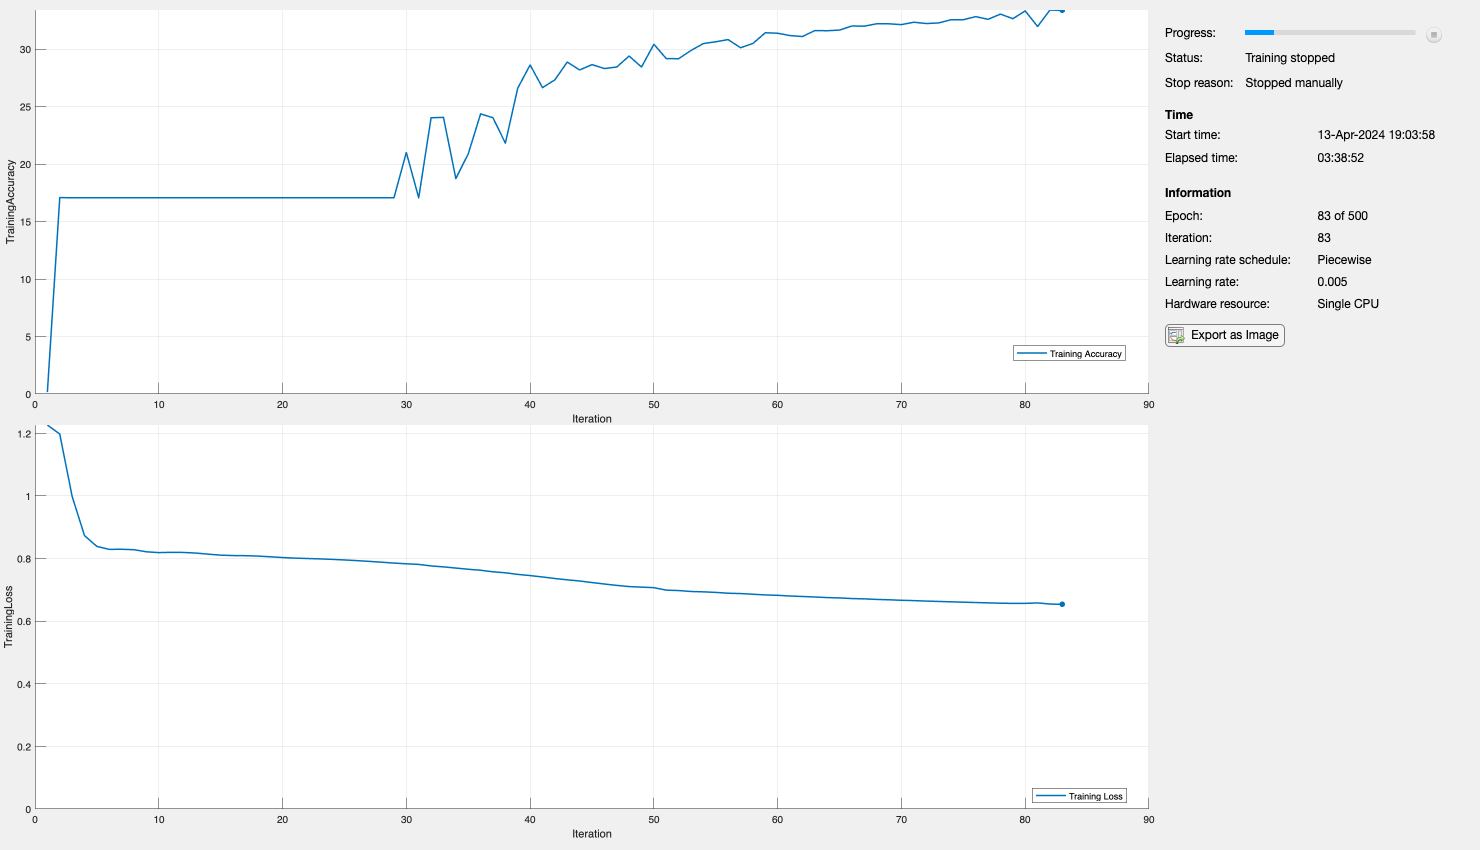

[net, info] = trainnet(XTrain,YTrain,layers,"crossentropy",options);

## Generate New Text

Use the `generateText` function, listed at the end of the example, to generate text using the trained network.

The `generateText` function generates text character by character, starting with the start of text character and reconstructs the text using the special characters. The function samples each character using the output prediction scores. The function stops predicting when the network predicts the end-of-text character or when the generated text is 500 characters long.

Generate text using the trained network.

vocabulary = string(categories(Y));
generatedText = generateText(net,vocabulary,uniqueCharacters,startOfTextCharacter,newlineCharacter,whitespaceCharacter,endOfTextCharacter)

datasample requires Statistics and Machine Learning Toolbox.

Error in ps3>generateText (line 110)
    newCharacter = datasample(vocabulary,1,'Weights',characterScores);

## Text Generation Function

The `generateText` function generates text character by character, starting with the start of text character and reconstructs the text using the special characters. The function samples each character using the output prediction scores. The function stops predicting when the network predicts the end-of-text character or when the generated text is 500 characters long.

function generatedText = generateText(net,vocabulary,uniqueCharacters,startOfTextCharacter,newlineCharacter,whitespaceCharacter,endOfTextCharacter)

Create the vector of the start of text character by finding its index.

numUniqueCharacters = numel(uniqueCharacters);
X = zeros(numUniqueCharacters,1);
idx = strfind(uniqueCharacters,startOfTextCharacter);
X(idx) = 1;

Generate the text character by character using the trained LSTM network using `predict` and `datasample`. Stop predicting when the network predicts the end-of-text character or when the generated text is 500 characters long. The `datasample` function requires Statistics and Machine Learning Toolbox™. 

For large collections of data, long sequences, or large networks, predictions on the GPU are usually faster to compute than predictions on the CPU. Otherwise, predictions on the CPU are usually faster to compute. For single time step predictions, use the CPU. To use the CPU for prediction, set the `'ExecutionEnvironment'` option of `predict` to `'cpu'`.

generatedText = "";
maxLength = 500;
while strlength(generatedText) < maxLength
    % Predict the next character scores.
    [characterScores,state] = predict(net,X,InputDataFormats='CTB');
    net.State = state;
    % Sample the next character.
    newCharacter = datasample(vocabulary,1,'Weights',characterScores);
    
    % Stop predicting at the end of text.
    if newCharacter == endOfTextCharacter
        break
    end
    
    % Add the character to the generated text.
    generatedText = generatedText + newCharacter;
    
    % Create a new vector for the next input.
    X(:) = 0;
    idx = strfind(uniqueCharacters,newCharacter);
    X(idx) = 1;
end

Reconstruct the generated text by replacing the special characters with their corresponding whitespace and newline characters.

generatedText = replace(generatedText,[newlineCharacter whitespaceCharacter],[newline " "]);

end

*Copyright 2018-2024 The MathWorks, Inc.*